# ** Task 2**

## **A.**

[x , fs] = audioread('MeriAwaz_25100225.wma')

x =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001


fs =        48000



% x is already mono, so no need of taking only single column

## B.

[X , f] = frft(x , fs)

X =   -0.0001 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0001 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i


f = 	1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013


## C.

Y = abs(X)

Y =     0.0001
    0.0000
    0.0000
    0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000


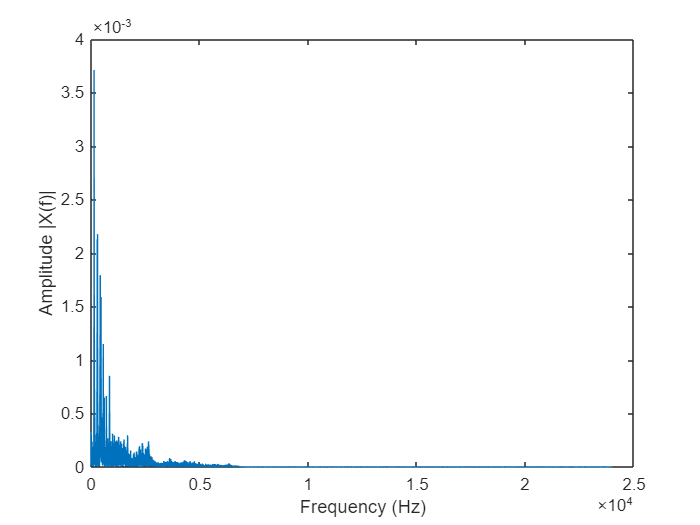

plot(f , Y)
xlabel('Frequency (Hz)')
ylabel('Amplitude |X(f)|')

## D.

[xi, t] = invfrft(X, f, fs)

xi =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001


t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


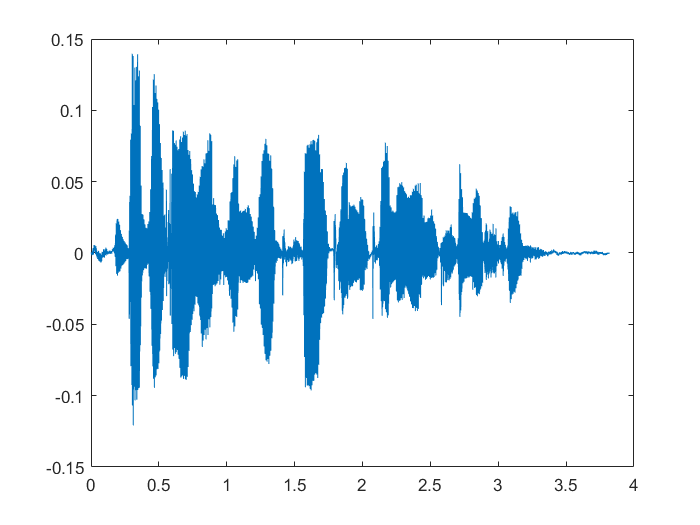

plot(t , xi)


diff = sum(abs(x - xi))

diff =      1.703986899908108e-12


# **Task 3**

## **A.**

[x , fs] = audioread('MeriAwaz_25100225.wma')

x =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001


fs =        48000


[X , f] = frft(x , fs)

X =   -0.0001 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0001 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i


f = 	1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013


## **B.**

TE = sum(abs(X).^2)

TE =      6.093790471117315e-04


## C.

CE = cumsum(abs(X).^2)

CE = 	1.0e+-3 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


## D.

max_index = max(find(CE<(0.95*TE)))

max_index =         6559



format long
frequency_max_index = f(max_index)

frequency_max_index =      1.717353351955307e+03


%testing
CE(max_index) < 0.95*TE  % should be boolean true (1)

ans = logical
   1


CE(max_index+1) < 0.95*TE % should be boolean false (0)

ans = logical
   0


# **Task 4 Bonus**

**A.**

[x , fs] = audioread('MeriAwaznoisy.wav')

x =    -0.0004
   -0.0000
    0.0004
    0.0006
    0.0004
         0
   -0.0004
   -0.0005
   -0.0003
         0


fs =        44100


[X , f] = frft(x , fs)

X =   -0.0001 + 0.0000i
  -0.0002 + 0.0002i
  -0.0001 + 0.0002i
   0.0001 + 0.0001i
   0.0001 + 0.0001i
   0.0001 + 0.0000i
   0.0000 - 0.0001i
   0.0000 - 0.0001i
  -0.0000 - 0.0000i
  -0.0001 - 0.0000i


f = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008


**B.**

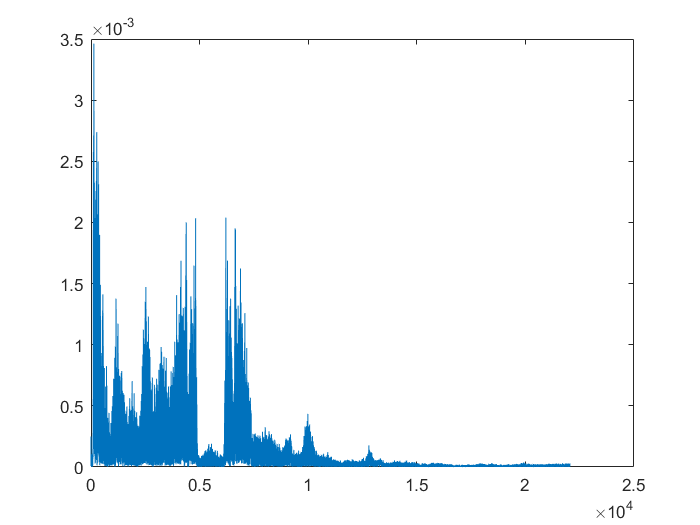


plot(f, abs(X))

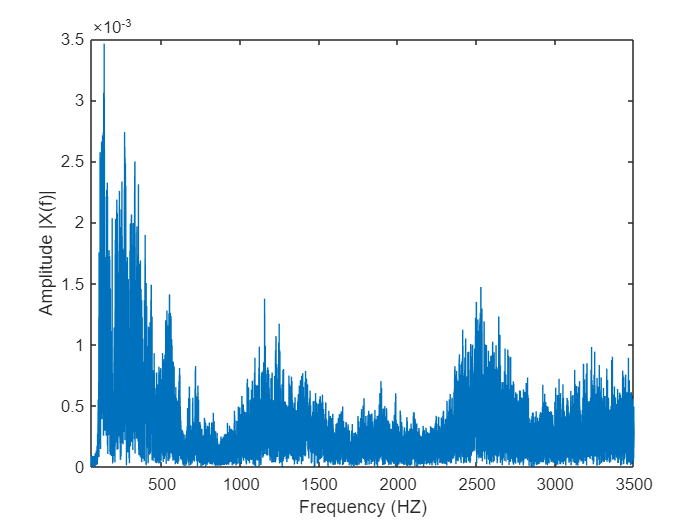

plot(f , abs(X))
xlabel('Frequency (HZ)')
ylabel('Amplitude |X(f)|')

xlim([50 3500])

**C.**

[y, t] = invfrft(X, f, fs)

y =    -0.0004
   -0.0000
    0.0004
    0.0006
    0.0004
    0.0000
   -0.0004
   -0.0005
   -0.0003
    0.0000


t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


sound(y, t)

Error using sound (line 79)
SAMPLERATE must be specified as a finite scalar value.

audiowrite("MeriAwazfiltered_25100225.wav")
